# Informe Laboratorio: Análisis Numérico

# Práctica No. 9: Numerical Integration

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

25 de Febrero del 2021

### 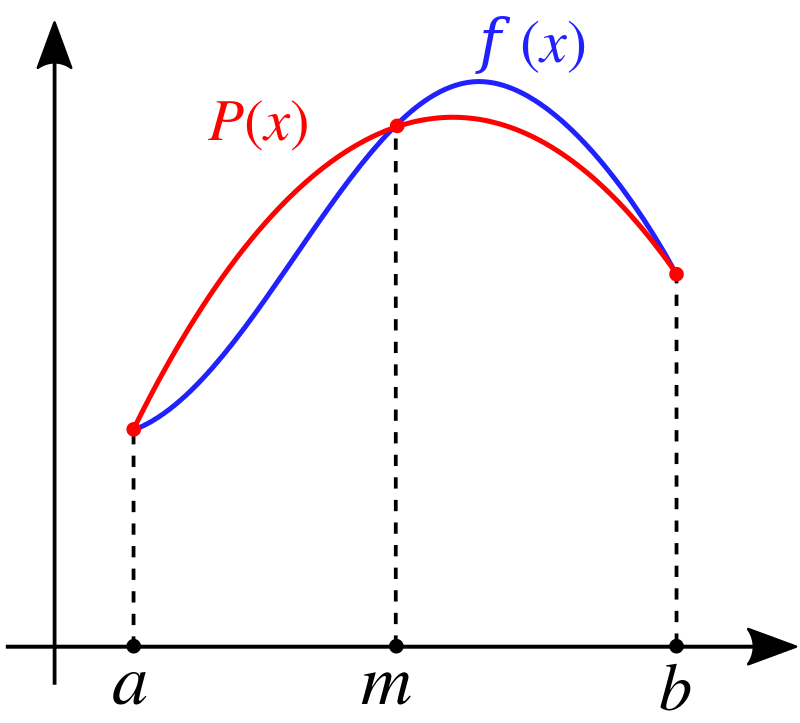

### Introduction:

In the following laboratory, the theme of numerical integration will be evaluated using as a basis the creation of two programs, one for the Simpson method and the other for the trapezoidal method, in such a way that by means of different exercises which present us with a specific function and we will have to design the way to calculate their respective integrals taking into account the limits of integration, and finally do the analysis on whether the values are similar or different with respect to the function.

### 3 Practice

###  3.1 Applying

- ** (0.5 points) Integrate **$f\left(x\right)=\textrm{xln}\left(x\right)$** over [1, 2] using the trapezoidal rule with step size h = 0.25. **

To solve the following exercise we must apply the trapezoid rule, and after this define the intervals to be determined within the given function


$$\frac{0\ldotp 25}{2}*\left(\mathrm{ln}\left(1\right)+2\left(1\ldotp 25\mathrm{ln}\left(1\ldotp 25\right)\right)+2\left(1\ldotp 5\mathrm{ln}\left(1\ldotp 5\right)\right)+2\left(1\ldotp 75\mathrm{ln}\left(1\ldotp 75\right)\right)+2\mathrm{ln}\left(2\right)\right)$$


clear all
close all
f= @(x) x*log(x);
a=1;
b=2;
h=0.25;
M=(b-a)/h;
disp('The following result is given by the trapezoidal rule:');

The following result is given by the trapezoidal rule:


Trapezoidal_Function=my_trapezoidal_function_Juan_Jimenez(f,a,b,M)

Trapezoidal_Function =    0.639900477687986


- **(0.5 points) Integrate**$f\left(x\right)=\textrm{xln}\left(x\right)$** over [1, 2] using the Simpson’s rule with step size h = 0.25.**


$$\frac{0.25}{3}\left(ln\left(1\right)+4\left(1.25ln\left(1.25\right)\right)+2\left(1.5ln\left(1.5\right)\right)+4\left(1.75ln\left(1.75\right)\right)+2ln\left(2\right)\right)$$


clear all
close all
f= @(x) x*log(x);
a=1;
b=2;
h=0.25;
M=(b-a)/(2*h);
disp('The following result is given by the Simpson rule:');

The following result is given by the Simpson rule:


Simpson_Function = my_simpson_function_Juan_Jimenez(f,a,b,M)

Simpson_Function =    0.636309829796949


### Analysis:

For the first exercise we are asked to determine both by the trapezoid method and by the simpson method the estimated value of the function f (x) = ln (x) whose given interval is [1,2], and our value of h = 0.25. Having said the above, the first thing is to create the programs for each of the methods taking into account that each one uses a different formula to determine the estimated value. After that for each method we define the value of a and b which are defined as the limits of integration of origin and end. In addition to defining M as the number of subintervals, although in this case the formula is used to make the respective calculation and finally f is defined as the function. If we realize the values are quite similar and this is thanks to the type of function that it has to work with and the way in which the code was defined in the annex

### 3.2 Implementing

-   (1.0 point) Create a Matlab function called my trapezoidal function name lastname() to approximate an integral using the composite trapezoidal rule. The arguments of the function must be: the function to be integrated f(x) (as an inline function), the limits of integration [a, b], and the the value of M. Make a script called run 3a name lastname.m in which you use the created function to solve the exercise in 3.1 and determine the root. For instance

clear all
close all
format long
f=@(x)(1/2)*exp(x.*2.5);
a=3;
b=4;
M=10;
disp('The following result is given by the trapezoidal rule:');

The following result is given by the trapezoidal rule:


Trapezoidal_Function=my_trapezoidal_function_Juan_Jimenez(f,a,b,M)

Trapezoidal_Function =      4.064723627960060e+03


- (1.0 point) Create a Matlab function called my simpson function name lastname() to approximate an integral using the composite Simpson’s rule. The arguments of the function must be: the function to be integrated f(x) (as an inline function), the limits of integration [a, b], and  the value of M. Make a script called run 3b name lastname.m in which you use the created function to solve the exercise in 3.1 and determine the root. For instance,

clear all
close all
f=@(x)(1/2)*exp(x.*2.5);
a=3;
b=4;
M=10;
disp('The following result is given by the Simpson rule:');

The following result is given by the Simpson rule:


Simpson_Function = my_simpson_function_Juan_Jimenez(f,a,b,M)

Simpson_Function =      4.043690150483193e+03


### Analysis for pint 3.2:

exercise was f (x) = ( 1/2) * exp (x. * 2.5) which in this case takes as a basis some of the functions shown in the Dennis Zill book on integral calculus, and makes some changes when defining the function. After that, determine the values of the integration limits [a, b] which I defined as [3,4]. And in addition to this, he defined the value of M as the number of subintervals to use. Something that I would like to highlight for the analysis of results is that I had to vary the function and the integration limits a lot since the result of both functions was very different and I was trying to find a function that could give me two values that are very similar to each other. , despite the fact that the two methods use different formulas. The result was two values of 4.06472 for the trapezoidal rule and 4.04369 for Simpson's rule, which are very quite equal to each other.

### 3.3 Interpreting

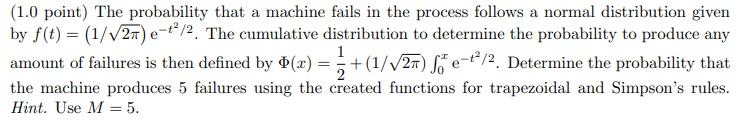

clc
close all
clear all
format long
disp('The following result is given by the Simpson rule:');

The following result is given by the Simpson rule:


f = @(t) exp((-t.^2)/2);
disp('Now we define the values for the upper and lower limits of integration and the value of M:');

Now we define the values for the upper and lower limits of integration and the value of M:


a=4;
b=5;
M=5;
disp('First we need to find the theoric value of the function:')

First we need to find the theoric value of the function:


theoric_value=integral(f,a,b)

theoric_value =      7.866950133653475e-05


disp('The following result is given by the Simpson rule:')

The following result is given by the Simpson rule:


Simpson_value = my_simpson_function_Juan_Jimenez(f,a,b,M)

Simpson_value =      7.867887125107086e-05


disp('The following result is given by the Trapezoidal rule:')

The following result is given by the Trapezoidal rule:


Trapezoidal_value = my_trapezoidal_function_Juan_Jimenez(f,a,b,M)

Trapezoidal_value =      8.304267107323989e-05


disp('Now we need to determine the probability of the Simpson rule using the formula in the header and multiplying this by the value given in the Simpson method:')

Now we need to determine the probability of the Simpson rule using the formula in the header and multiplying this by the value given in the Simpson method:


Simpson_probability=(1/2)+ (1./sqrt(2*pi)).*Simpson_value

Simpson_probability =    0.500031388328316


disp('Now we need to determine the probability of the trapezoidal rule using the formula in the header and multiplying this by the value given in the trapezoidal method:')

Now we need to determine the probability of the trapezoidal rule using the formula in the header and multiplying this by the value given in the trapezoidal method:


Trapezoidal_probability =(1/2)+ (1./sqrt(2*pi)).*Trapezoidal_value

Trapezoidal_probability =    0.500033129232569


disp('finally the error for the Simpson rule must be determined')

finally the error for the Simpson rule must be determined


relative_error_for_Simpson_rule=abs((Simpson_value)./(theoric_value)).*100

relative_error_for_Simpson_rule =      1.000119104791271e+02


disp('finally the error for the trapezoidal rule must be determined')

finally the error for the trapezoidal rule must be determined


relative_error_for_Trapezoidal_rule=abs((Trapezoidal_value)./(theoric_value)).*100

relative_error_for_Trapezoidal_rule =      1.055589137625234e+02


### Analysis:

For the following exercise we are asked to determine several things, the first thing is that they give us the respective function f (x) and from this we will have to define the limits of integration, the value of M = 5 and perform the calculations for the respective methods Simpson's and trapezoidal, but the theoretical value of the integral must be determined first and after that if both integration rules are used. Once these values have been determined, the probability of each of the methods is determined using the formula that is presented in the heading of the exercise and after them we determine the error for each of the methods where we can see that they are similar to each other. each of the values

### 3.4 Proposing 

-  (0.5 points) Propose an application problem in which the trapezoidal and Simpson’s rules can be used. 

The following exercise requires analyzing the distance Juan Pablo Montoya travels in his race car in time intervals. The speed at which the car runs on the race track is determined by the function f (x) $10x^3 -e^{-5x} +11$m/s. From the previous data, it is necessary to determine how much distance the maximum speed knowing that this is reached in the first 13 seconds of the race with h = 0.5.

-  (0.5 points) Solve the proposed problem using the created functions

clear all
close all
f= @(x) 10*x.^3+exp(-5*x)+11;
a=0;
b=13;
h=0.5;
M=(b-a)/h;
%M=(b-a)/(2*h);
disp('The following results are for the distance traveled at 13 seconds for Simpson rule and the trapezoidal rule:')

The following results are for the distance traveled at 13 seconds for Simpson rule and the trapezoidal rule:


disp('The following result is given by the trapezoidal rule:');

The following result is given by the trapezoidal rule:


Trapezoidal_Value=my_trapezoidal_function_Juan_Jimenez(f,a,b,M)

Trapezoidal_Value =      7.165141971274492e+04


disp('The following result is given by the Simpson rule:');

The following result is given by the Simpson rule:


Simpson_Value = my_simpson_function_Juan_Jimenez(f,a,b,M)

Simpson_Value =      7.154570227945785e+04



disp('the maximum speed in m/s at which the car travels determined by the data of 18 seconds is:')

the maximum speed in m/s at which the car travels determined by the data of 18 seconds is:


maximum_speed=f(13)

maximum_speed =        21981


### Analysis:

Having proposed the exercise based on some applications from Dennis Zill's book on integral calculus, we solve the exercise using the trapezoidal rule and Simpson's rule as we did in the previous exercises. We define the values of the [a, b] which in this case will go from 0 to 15, and after that we define the value of h = 0.5 which gives us the exercise, we define the opration for M, first we have the result of the distance traveled in those first 15 seconds, something to note is that the distances are quite similar for both methods. finally we do the calculation to determine the maximum speed after 15 seconds, which was 21981 m / s

### ANEXES

**The functions below were taken from the matlab method book**

**my_trapezoidal_*****function_Juan_Jimenez*****()**

function T = my_trapezoidal_function_Juan_Jimenez(f,a,b,M)
h=(b-a)/M;
T=0;
for k=1:(M-1)
    x=a+h*k;
  T=T+feval(f,x);
end
T=h*(f(a)+f(b))/2+h*T;
end


    

**my_simpson_*****function_Juan_Jimenez*****()**

function s = my_simpson_function_Juan_Jimenez(f,a,b,M)
h=(b-a)/(2*M);
s1=0;
s2=0;
for k=1:M
    x=a+h*(2*k-1);
    s1=s1+feval(f,x);
end
for k=1:(M-1)
x=a+h*2*k;
s2=s2+feval(f,x);
end
s=h*(feval(f,a)+feval(f,b)+4*s1+2*s2)/3;
end




### References:

- Miranda, J. (2021). Cálculo, 4ta Edición Dennis G. Zill FREELIBROS. Retrieved 25 February 2021, from [https://www.academia.edu/34836465/C%C3%A1lculo_4ta_Edici%C3%B3n_Dennis_G_Zill_FREELIBROS](https://www.academia.edu/34836465/C%C3%A1lculo_4ta_Edici%C3%B3n_Dennis_G_Zill_FREELIBROS)

- 하람, 유. (2020). Solutions Manual to accompany Applied Numerical Methods With MATLAB for Engineers and Scientists. Retrieved 26 November 2020, from [https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists](https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists)

- Regla de Simpson. (2021). Retrieved 25 February 2021, from [https://es.wikipedia.org/wiki/Regla_de_Simpson](https://es.wikipedia.org/wiki/Regla_de_Simpson)

- Integración numérica. (2021). Retrieved 25 February 2021, from [https://www.unioviedo.es/compnum/laboratorios_web/Laborat10_inte/Laborat07b_integracion.html](https://www.unioviedo.es/compnum/laboratorios_web/Laborat10_inte/Laborat07b_integracion.html)

- (2021). Retrieved 25 February 2021, from [https://fjarabo.webs.ull.es/VirtualDoc/Curso%202011-2012/Ingenier%C3%ADa%20Qu%C3%ADmica/2_Teoria/Tema_6_Ingenieria_de_la_Reaccion_Quimica/A60/603_Integracion_grafica_por_Trapecios.pdf](https://fjarabo.webs.ull.es/VirtualDoc/Curso%202011-2012/Ingenier%C3%ADa%20Qu%C3%ADmica/2_Teoria/Tema_6_Ingenieria_de_la_Reaccion_Quimica/A60/603_Integracion_grafica_por_Trapecios.pdf)